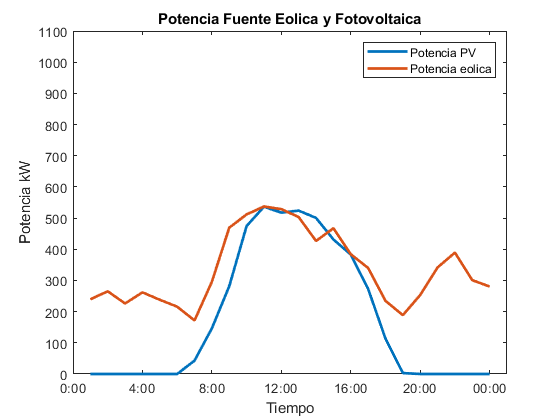







clear  
close all
clc
tiempo = linspace(1,24,24); % Vector de tiempo de 0 a 24 horas con 96 puntos (cada 15 minutos)


%%datos de los generadores
%wind=[250,206,233,194,200,187,111,174,276,301,316,311,296,251,275,226,200,138,111,149,201,229,177,165]*1.7;
irrad=[0,0,0,0,0,0,86,293,563,949,1073,1035,1048,1001,863,766,546,227,6,0,0,0,0,0]*0.5;
wind=[141,156,133,154,140,127,101,174,276,301,316,311,296,251,275,226,200,138,111,149,201,229,177,165]*1.7;


plot(tiempo,irrad,'linewidth',2)
hold on
plot(tiempo,wind,'linewidth',2)
ylim([0 1100])
title('Potencia Fuente Eolica y Fotovoltaica')
xlabel('Tiempo')
ylabel('Potencia kW')
legend('Potencia PV','Potencia eolica')
xticks(0:4:24); % Establecer las marcas (ticks) cada 4 horas
% Crear etiquetas personalizadas para cada tick (4 horas)
xticklabels({'0:00', '4:00', '8:00', '12:00', '16:00', '20:00', '00:00'});
hold off





%%definimos el numero de periodos
T=24;
N_u=2;
Nload = 1;
%%parametros bateria 

SOC_0 = 0.4; % Estado de carga inicial 
SOC_min=0.2;
SOC_max= 0.95;

%%%%%%%%%%%%%%%%%%

%%%% parametros trubina de gas %%

a=[0.008 0.008];    %%Fuel cost factor a
b=[0.04  0.04] ;    %%Fuel cost factor b
c=[42  42];         %%Fuel cost facto c
C_Gs=[308 340];        %%star-up cost(yuan)  
C_Gt=[248 260];        %%shutdown cost(yuan)
PGi__max=[800 1000];       %%the upper limit of output(kW)
PGi__min=[300 500];        %%the lower limit of output(kW)
Pci=[400 500];       %%climbing power(kW)

lambda_Gi= 0.76; %% kg/kWh emision de carbono de referencia por unidad de electricidad


%%variblaes costos de operacion y mantenimiento de generadores eolico y
%%fotovoltaico
Swind= 0.52;
Ssol= 0.72;
Ssto= 0.5;

%%variable de precio de veenta y compra de electricidad de la red electrica
C_buy= [0.30 0.30 0.30 0.30 0.30 0.30 0.61 0.86 0.86 0.86 0.86 0.61 0.61 0.86 0.86 0.86 0.86 0.86 0.61 0.61 0.61 0.30 0.30 0.3];
C_sell=[0.26 0.26 0.26 0.26 0.26 0.26 0.50 0.68 0.68 0.68 0.68 0.50 0.50 0.68 0.68 0.68 0.68 0.68 0.50 0.50 0.50 0.26 0.26 0.26];

%%precio de incentivo en la respuesta a la demanda
p_e_sub = [0.25 0.25 0.25 0.25 0.25 0.25 0.25 0.25 0.53 0.95 0.95  0.53 0.53 0.53 0.53 0.53 0.95 0.95 0.95 0.95 0.95 0.25 0.25 0.25  ];

%%variables de decisión
P_w = wind';
P_sol = irrad';
P_G = sdpvar(T, N_u,'full'); % Potencia generada por unidades térmicas
P_buy = sdpvar(T,1);  % Potencia
P_sell= sdpvar(T,1);
Pload_DRi=[676,683,664,662,677,658,604,1204,1745,1937,2162,2027,1731,1633,2022,2220,2296,2349,2149,1728,967,743,632,600]*1.15; % Datos de carga para cada hora del día

Pnet = sdpvar(T, 1); % Potencia intercambiada con la red
% Pbat = sdpvar(T, 1); % Potencia de salida de la batería
% Pcha = sdpvar(T, 1); % Potencia de carga de la batería en cada intervalo de tiempo
% Pdis = sdpvar(T, 1); % Potencia de descarga de la batería en cada intervalo de tiempo
% Ebat = sdpvar(T, 1); % Carga de la batería
%%variables Binarias 
%DR_reduction=sdpvar(T,Nload) % reduccion de la demanda 
%Demanda_modificada = sdpvar(T, 1);  % Variable de decisión para la demanda ajustada


delta_Gs = binvar(T,N_u);
delta_Gt = binvar(T,N_u);
delta_Gr = binvar(T,N_u); % Variables binarias para estado (encendido/apagado)

delta_bs = binvar(T, 1); % Variable booleana para compra/venta de electricidad
delta_cha = binvar(T, 1); % Variable booleana para cargar la batería
delta_dis = binvar(T, 1); % Variable booleana para descargar la batería
delta_sta = binvar(T, 1); % 1 si la batería está inactiva, 0 de lo contrario


%% costos operativos y de mantenimiento de los generadores fotovoltaico y eolico.
%% costos operativos de la turbina de gas
%% costos por compra y la venta de electricidad
%% costos por emision de carbono
%% costos de respuesta a la demanda


%% cada parte de la ecuacion tiene su equivalente
C_op = sum(Swind*P_w + Ssol*P_sol );%+ Ssto * Pdis );
C_th = sum(sum(a(1)* P_G.^2 + b(1)* P_G + c(1) + delta_Gs* C_Gs(1) + delta_Gt*C_Gt(1)));
C_bs = sum(C_buy*P_buy + C_sell*P_sell);


% Emisiones de carbono y biomasa
beta_et_j = [0.2278, 0.2401, 0.2156, 0.2305, 0.2250 0.2278, 0.2401, 0.2156, 0.2305, 0.2250 0.2278, 0.2401, 0.2156, 0.2305, 0.2250 0.2278, 0.2401, 0.2156, 0.2305, 0.2250 0.2278, 0.2401, 0.2156, 0.2305];
EG_c = sum(sum(beta_et_j* P_G));
EG_b = sum(sum(lambda_Gi* P_G));
% Costo de emisiones
lambda_E=30; 
C_ce = lambda_E * EG_c - lambda_E * EG_b;


                                            
% nu = 0.3 * ones(1, T); % Incentivo o penalización fija para cada intervalo de tiempo [1 x T]
% lambda_Ei = 0.25 * ones(1, T); % Coeficiente de DR fijo para cada intervalo de tiempo [1 x T]
% Pload_DRi =  sdpvar(Nload,T);
% PloadDR=sdpvar(T,1)
%C_DR = sum(sum(p_e_sub.* Pload_DR + nu./lambda_Ei));
%


## Modelado de costos de operacion de vehiculos electricos

precios_cha = [0.02 0.02 0.02 0.02 0.02 0.02 0.02 0.04 0.07 0.07 0.75 0.04 0.04 0.04 0.04 0.04 0.04 0.07 0.075 0.075 0.07 0.07 0.02 0.02]

precios_cha =     0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0400    0.0700    0.0700    0.7500    0.0400    0.0400    0.0400    0.0400    0.0400    0.0400    0.0700    0.0750    0.0750    0.0700    0.0700    0.0200    0.0200


precios_dis = [0.03 0.03 0.03 0.03 0.03 0.03 0.03 0.06 0.10 0.10 0.11 0.06 0.06 0.06 0.06 0.06 0.06 0.06 0.10 0.11 0.11 0.10 0.03 0.03  ]

precios_dis =     0.0300    0.0300    0.0300    0.0300    0.0300    0.0300    0.0300    0.0600    0.1000    0.1000    0.1100    0.0600    0.0600    0.0600    0.0600    0.0600    0.0600    0.0600    0.1000    0.1100    0.1100    0.1000    0.0300    0.0300


eta_c = 0.95; % Eficiencia de carga
eta_d = 0.95; % Eficiencia de descarga
E_max = 100; % Capacidad máxima de la batería
S_min = 0.2; % SOC mínimo
S_max = 0.85; % SOC máximo
S_arrival = 0.2; % SOC al momento de llegada
S_target = 0.85; % SOC objetivo al momento de salida
Delta_t = 0.25; % Duración del intervalo de tiempo (ejemplo: 0.25 h)

Nv = 2; % Número de EVs

% Variables de decisión
ucv = binvar( T,Nv,'full'); % Variable binaria de estado de carga
udv = binvar(T,Nv,'full'); % Variable binaria de estado de descarga
uin = binvar(T,Nv,'full'); % Variable binaria de conexión del EV
S = sdpvar(T,Nv,'full'); % SOC de cada EV
Pcv = sdpvar(T,Nv,'full'); % Potencia de carga para cada EV
Pdv = sdpvar(T,Nv,'full'); % Potencia de descarga para cada EV
pc_v = 10; % Potencia máxima de carga
pd_v = 10; % Potencia máxima de descarga



## Inicializar restricciones



constraints=[];




for v = 1:Nv
    %S(v, 1) = S_arrival
    % Definir el SOC inicial al llegar
    constraints = [constraints, S(v, 1) == S_arrival];
    for t = 2:T
        constraints = [constraints, Pcv(t,v) == ucv(t,v) * pc_v]; % Potencia de carga
        constraints = [constraints, Pdv(t,v) == udv(t,v) * pd_v]; % Potencia de descarga
        constraints = [constraints, ucv(t,v) + udv(t,v) <= uin(t,v)]; % Estado de operación
        constraints = [constraints, S_min <= S(t,v) <= S_max]; % Restricciones de SOC

        % Cambio de SOC en periodos consecutivos
        constraints = [constraints, S(t,v) == S(t-1,v) + ...
            ((ucv(t,v) * pc_v * eta_c) / E_max - (udv(t,v) * pd_v) / (E_max * eta_d)) * Delta_t];
    end
    % Restricción de SOC en el tiempo final
    constraints = [constraints, S(T,v) >= S_target];
end

% Función de costo
CEV = sum(sum(precios_dis * Pdv - precios_cha * Pcv));


## Funcion de costos a minimizar





%%-213261

    Restricciones

## Restricción de la turbina de gas.


% Restricciones para generadores térmicos
for t = 1:T
    for i = 1:N_u
        % Restricciones de potencia mínima y máxima con variables binarias
        constraints = [constraints, ...
            (delta_Gr(t, i) * PGi__min(i) <= P_G(t, i)) <= delta_Gr(t, i) * PGi__max(i)];
    end
end

%% Restricciones de rampa de potencia
for t = 1:T-1 % T-1 porque estamos considerando PGi(t+1)
    for i = 1:N_u
        % Restricción de cambio de potencia entre periodos consecutivos
        constraints = [constraints, ...
            -Pci(i) <= P_G(t+1, i) - P_G(t, i) <= Pci(i)];
    end
end

% Restricción de estado de generadores térmicos (no pueden estar encendidos y apagados simultáneamente)
for t = 1:T
    for i = 1:N_u
        constraints = [constraints, delta_Gs(t, i) + delta_Gt(t, i) <= 1];
    end
end

% Restricción de cambio de estado
delta_Gr_diff = sdpvar(T-1, N_u); % Diferencia de estado de encendido/apagado

% Calcular la diferencia de estado de encendido para cada generador y período
for t = 1:T-1
    for i = 1:N_u
        delta_Gr_diff(t, i) = delta_Gr(t+1, i) - delta_Gr(t, i);
    end
end

%% Restricción que asegura que el número total de cambios de estado no exceda el número de cambios posibles
sum_delta_Gdiff= sum(sum(delta_Gs - delta_Gt));

sum_delta_Gr_diff = sum(sum(delta_Gr_diff));



constraints = [constraints, sum_delta_Gr_diff <= sum_delta_Gdiff];


## restricciones de balance de potencia



% Añadir la restricción de balance de potencia para cada período de tiempo
Pload=[825,900,1190,1171,1300,1250,1354,1204,1745,1937,2162,2027,1731,1633,2022,2220,2296,2349,2149,1728,967,743,632,600]*0.9; % Datos de carga para cada hora del día


%Pload=2000*ones(1,24)
for t = 1:T
    constraints = [constraints, ...
        Pnet(t) + wind(t) + irrad(t) + sum(P_G(t, :)) + sum(Pcv(t,:))  ==  Pload(t) + sum(Pdv(t,:)) ];
end


## restricciones de compra y venta de electricidad de la VPP


Ppower = 200;           % Límite de potencia de intercambio

% Límite de Pnet
constraints = [constraints, -Ppower <= Pnet <= Ppower];
% Límite de Psell
constraints = [constraints, -Ppower <= P_sell <= 0];
% Límite de Pbuy
constraints = [constraints, 0 <= P_buy <= Ppower];


constraints= [constraints,[implies(Pnet>=0, Pnet==P_buy),implies(delta_bs==1,Pnet==P_buy)]];
constraints= [constraints,[implies(Pnet<=0, Pnet==P_sell),implies(delta_bs==0,Pnet==P_sell)]];




##  Restricción de incentivos DR.

Fmin = 0.1; % Valor mínimo de fluctuación
Fmax = 0.8; % Valor máximo de fluctuación
chi = 0.5; % Valor máximo del coeficiente de respuesta a la demanda

% Variables de decisión
lambda_x = sdpvar(T, 1); % Coeficiente de respuesta a la demanda
W_DR = 1; % Factor de ponderación para cada usuario
Pload_i =[0.5, 0.4, 0.4, 0.3, 0.3, 0.6, 1.2, 1.5, 1.0, 0.8, 0.7, 0.6, ...
                    0.5, 0.5, 0.4, 0.6, 0.7, 1.2, 1.8, 2.0, 1.5, 1.0, 0.8, 0.6]; % kWh

% Coeficientes de respuesta a la demanda
lambda_min_x = 0.2; % Ejemplo de valor mínimo
lambda_max_x = 0.5; % Ejemplo de valor máximo

% Restricción de fluctuación
F_x = (lambda_max_x - lambda_min_x) / lambda_max_x;
constraints = [constraints, Fmin <= F_x, F_x <= Fmax];

% Restricción de capacidad de respuesta
%constraints = [constraints, (sum(lambda_min_x * W_DR * Pload_i) <= lambda_x )<= sum(lambda_max_x * W_DR * Pload_i)];


% Restricción del coeficiente de respuesta
constraints = [constraints, (0 <= lambda_x) <= chi];
%optimize(constraints)

## Resolver el problema

FminCvpp  =  C_ce     + C_th  +  C_bs + C_op + CEV ;

options = sdpsettings('verbose', 1, 'solver', 'Cplex'); 

sol = optimize(constraints,FminCvpp,options);

CPXPARAM_MIP_Display                             1

if sol.problem == 0
    % Si no hay errores
    fprintf('Optimización completada con éxito.\n');
    P_G_opt = value(P_G);
    P_w_opt = value(P_w);
    P_sol_opt = value(P_sol);
    
else
    disp('Problema en la optimización:');
    disp(yalmiperror(sol.problem));
end

Problema en la optimización:


Unbounded objective function (<a href="yalmip.github.io/debuggingunbounded">learn to debug</a>) 


## valores


% Obtén los valores de las variables de decisión
P_w_val = value(P_w);
P_sol_val = value(P_sol);
P_G_val = value(P_G);
P_buy_val = value(P_buy);
P_sell_val = value(P_sell);
Pload_DRi_val = value(Pload_DRi);
%Pload_DR_val = value(Pload_DR);
Pnet_val = value(Pnet);


%lambda_x_val = value(lambda_x);



% Muestra los valores
disp('Valores de las variables de decisión:');

Valores de las variables de decisión:


disp('P_w:');

P_w:


disp(P_w_val);

  239.7000
  265.2000
  226.1000
  261.8000
  238.0000
  215.9000
  171.7000
  295.8000
  469.2000
  511.7000
  537.2000
  528.7000
  503.2000
  426.7000
  467.5000
  384.2000
  340.0000
  234.6000
  188.7000
  253.3000
  341.7000
  389.3000
  300.9000
  280.5000



disp('P_sol:');

P_sol:


disp(P_sol_val);

         0
         0
         0
         0
         0
         0
   43.0000
  146.5000
  281.5000
  474.5000
  536.5000
  517.5000
  524.0000
  500.5000
  431.5000
  383.0000
  273.0000
  113.5000
    3.0000
         0
         0
         0
         0
         0



disp('P_G:');

P_G:


disp(P_G_val);

     0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0



disp('P_buy:');

P_buy:


disp(P_buy_val);

     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0



disp('P_sell:');

P_sell:


disp(P_sell_val);

  -200
  -200
  -200
  -200
  -200
  -200
  -200
  -200
  -200
  -200
  -200
  -200
  -200
  -200
  -200
  -200
  -200
  -200
  -200
  -200
  -200
  -200
  -200
  -200



disp('Pload_DRi:');

Pload_DRi:




disp('Pnet:');

Pnet:


disp(Pnet_val);

   1.0e-05 *

   -1.0000
   -1.0000
   -1.0000
   -1.0000
   -1.0000
   -1.0000
   -1.0000
   -1.0000
   -1.0000
   -1.0000
   -1.0000
   -1.0000
   -1.0000
   -1.0000
   -1.0000
   -1.0000
   -1.0000
   -1.0000
   -1.0000
   -1.0000
   -1.0000
   -1.0000
   -1.0000
   -1.0000









datos=[P_G_val(:,1),P_G_val(:,2), P_w_val, P_sol_val,Pnet_val]; %, -Pbat_val]
bar(datos,'stacked','FaceColor','flat' )
ylim([-500,3000])
title('Virtual power plant, demanda');
xlabel('Tiempo (h)');
ylabel('Potencia kW');
hold on
plot(Pload)
plot(value(Pload),'LineWidth',2.5)
legend({'G1', 'G2 ','wind', 'solar','Ptransferida','Pbat','Demanda','Demanda DR' }, 'Location', 'northwest'); % Leyenda

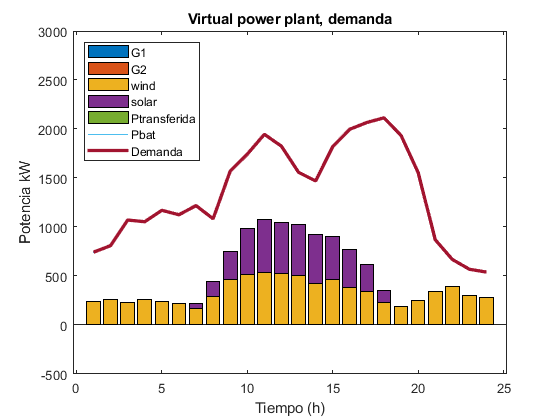


hold off


figure
datos1=[P_G_val(:,1),P_G_val(:,2),P_w_val, P_sol_val]%,Pbat_val];  %, -Pbat_val]

datos1 =          0         0  239.7000         0
         0         0  265.2000         0
         0         0  226.1000         0
         0         0  261.8000         0
         0         0  238.0000         0
         0         0  215.9000         0
         0         0  171.7000   43.0000
         0         0  295.8000  146.5000
         0         0  469.2000  281.5000
         0         0  511.7000  474.5000


bar(datos1,'stacked','FaceColor','flat')
ylim([-500,3000])
title('Virtual power plant, demanda');
xlabel('Tiempo (h)');
ylabel('Potencia kW');
legend({'Generador1', 'Generador 2 ','fuente eolica', 'Fuente solar','Potencia bateria' }, 'Location', 'northwest'); % Leyenda

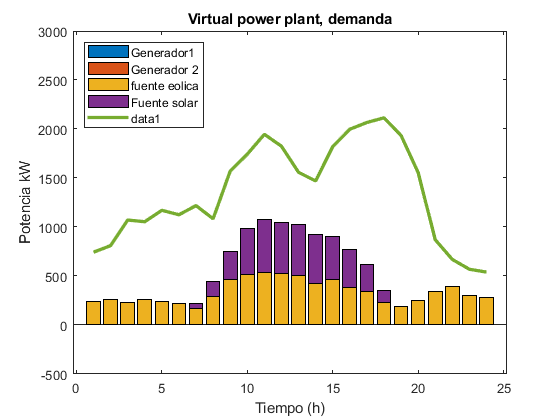

hold on
plot(value(Pload),'LineWidth',2.5)

hold off

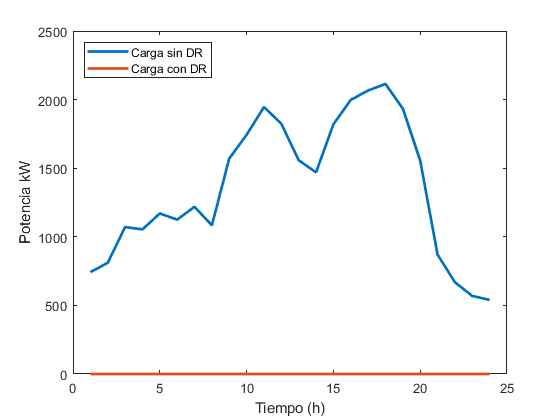


figure
plot(value(Pload),'LineWidth',2)
xlabel('Tiempo (h)');
ylabel('Potencia kW');
hold on 
plot(P_G_val(:,1)+P_G_val(:,2),'LineWidth',2)
legend({'Carga sin DR', 'Carga con DR '}, 'Location', 'northwest'); % Leyenda
hold off

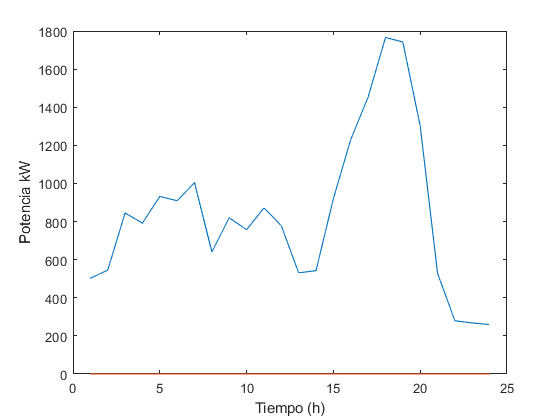


datos2 = P_G_val(:,1)+P_G_val(:,2)+ P_w_val+P_sol_val +Pnet_val;
figure

% plot(value(Pload),'LineWidth',2)
% hold on
plot(value(Pcv))
hold off
xlabel('Tiempo (h)');
ylabel('Potencia kW');

%legend({'Carga sin DR', 'Carga con DR '}, 'Location', 'northwest'); % Leyenda

%plot(value(DR_reduction),'LineWidth',2)
